clc; close all; clear all;
% generate training dataset

## Change the working path to the current folder

tmp = matlab.desktop.editor.getActive;                  % filep contains the path where this mlx-file is already located and the file name (with the .mlx suffix)
index = [strfind(tmp.Filename, '\')];
pathstr = tmp.Filename(1:index(end)-1);                 % pathstr is the path where this m file is located
cd(pathstr);                                            % Change the current Active Directory path

## 1. Shallow water environmet

An overview for shallow water environment sound propagation, including env file construction, flp file construction, sound speed profile visualizing, nomal mode calculation and visualization, acoustic field calculation and transmission loss visualization.

### 1.1. Write env file

folder='.\1.1.1 Narrowband Envfile';                    % Folder name definition
if exist(folder,'dir')==0                               % Determine if a folder exists
    mkdir(folder);                                      % Create a folder when it does not exist
else
    disp('dir is exist');                               % If the folder exists, output :dir is exist
end

dir is exist


cd(folder);                                             % Change the path to the environment file path

envfil = 'Shallow_water';                               % env file name
model = 'KRAKEN';                                       % env file type
% (1) - Title
TitleEnv = 'Sallow-water sea environment';              % env title

% (2) - Frequency
freq = 50;                                              % FREQ: Frequency in Hz.

% (3) - Number of Media
SSP.NMedia = 1;                                         % Number of media

% (4) - Top Option
Bdry.Top.Opt = 'CVF';                                   % Top option

% (5) - Sound Speed Profile
SSP.N(1) = 0;                                           % NMESH:        Number of mesh points used in the internal discretization.
SSP.sigma(1) = 0;                                       % SIGMA:        RMS roughness at the interface (ignored by BELLHOP and SPARC)
SSP.depth(2) = 100;                                     % Depth of the 2nd media (m).
SSP.raw(1).z = 0: 5 : 100;                              % z():          Depth (m)
SSP.Nz(1) = length(SSP.raw(1).z);                       % Number of z vector
SSP.raw(1).alphaR(1:SSP.Nz(1)) = 1540:-1:1520;          % alphaR():     P-wave speed (m/s).
SSP.raw(1).betaR(1:SSP.Nz(1)) = 0;                      % betaR():      S-wave speed (m/s).
SSP.raw(1).rho(1:SSP.Nz(1)) = 1.03;                     % rho():        Density (g/cm3).
SSP.raw(1).alphaI(1:SSP.Nz(1)) = 0;                     % alphaI():     P-wave attenuation (units as given in Block 2)
SSP.raw(1).betaI(1:SSP.Nz(1)) = 0;                      % betaI():      S-wave attenuation

% (6) - Bottom Option
Bdry.Bot.Opt = 'A';                                     % BOTOPT(1:1):  Type of bottom boundary condition.
SSP.depth( SSP.NMedia+1 ) = 100;                        % depth:        Depth (m).
Bdry.Bot.HS.alphaR = 1600;                              % alphaR:       Bottom P-wave speed (m/s).
Bdry.Bot.HS.betaR = 0;                                  % betaR:        Bottom S-wave speed (m/s).
Bdry.Bot.HS.rho = 1.9;                                  % rho:          Bottom density (g/cm3).
Bdry.Bot.HS.alphaI = 0.09;                              % alphaI:       Bottom P-wave attenuation. (units as given by TOPOPT(3:3) )
Bdry.Bot.HS.betaI = 0;                                  % betaI:        Bottom S-wave attenuation.

% (7) - Phase Speed Limits
cInt.Low = 0;                                           % CLOW:         Lower phase speed limit (m/s).
cInt.High = 2e4;                                        % CHIGH:        Upper phase speed limit (m/s).

% (8) - Maximum Range
RMax = 0;                                               % RMax:         Maximum range (km)

% (9) - Source/Receiver Depths
Pos.s.z = 5;                                            % Sz():         Source   depths (m).
Pos.r.z = 1:100;                                        % Rz():         Receiver depths (m).
Beam = [];                                              % Not used in kraken.

% Write env
write_env( envfil, model, TitleEnv, freq, SSP, Bdry, Pos, Beam, cInt, RMax );

### 1.2. Write flp file

flpfil = envfil;

%  (2) - OPTIONS
Option = 'RA';                                          % 'R' point source. 'A' Adiabatic mode theory (default).

%  (6) - SOURCE/RECEIVER LOCATIONS
Pos.r.r = 1:0.05:20;                                    % The receiver ranges (km)

% Write flp
write_fieldflp( flpfil, Option, Pos );

### 1.3. Read and plot sound speed profile

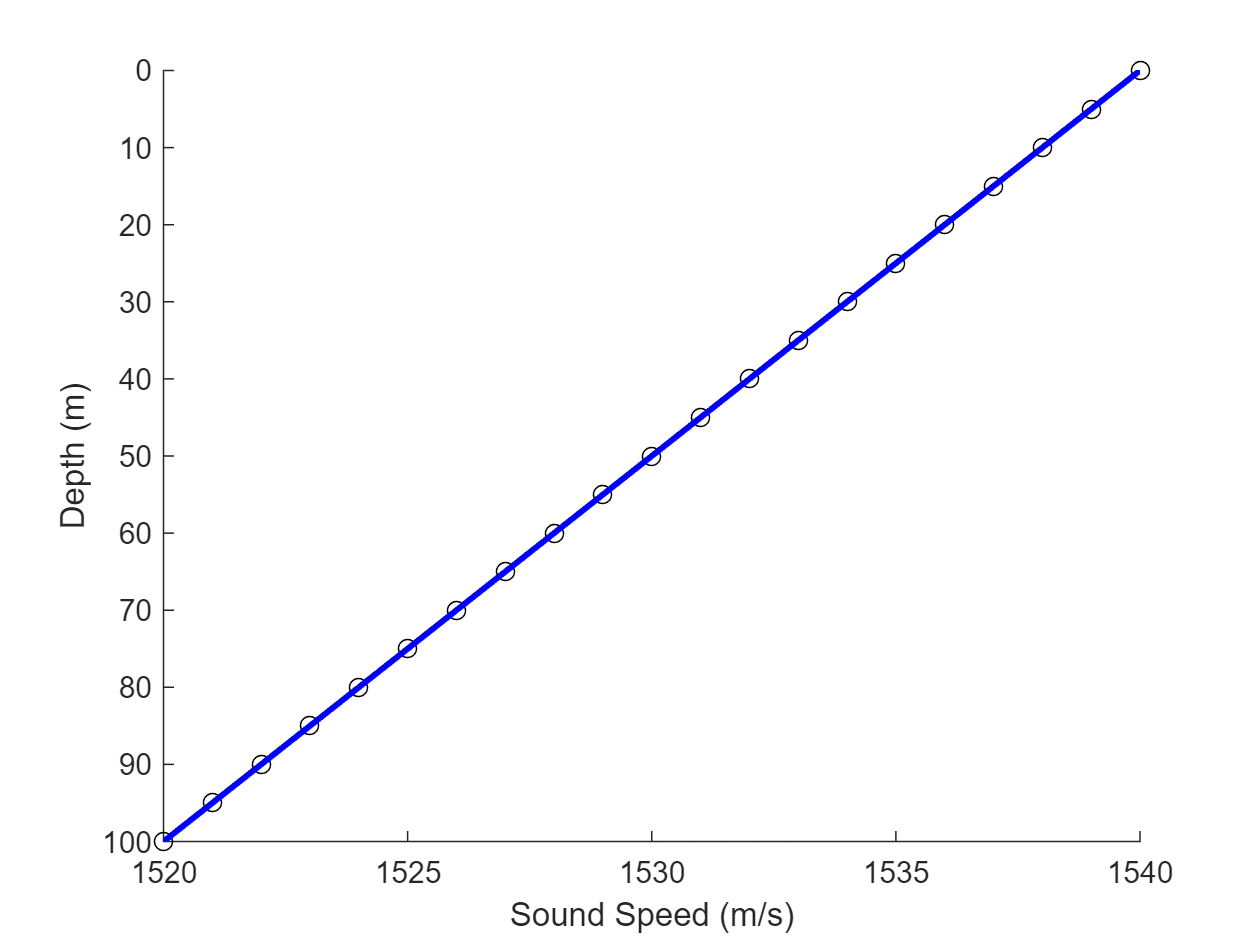

Sallow-water sea environment
Frequency = 50 Hz 
Number of media = 1 

    C-Linear approximation to SSP
    Attenuation units: dB/mkHz
    VACUUM

       z          alphaR         betaR           rho        alphaI         betaI
      (m)          (m/s)         (m/s)         (g/cm^3)      (m/s)         (m/s) 
    ( Number of points = 0  Roughness =   0.00  Depth =   100.00 ) 
      0.00       1540.00          0.00          1.00        0.0000        0.0000 
      5.00       1539.00          0.00          1.00        0.0000        0.0000 
     10.00       1538.00          0.00          1.00        0.0000        0.0000 
     15.00       1537.00          0.00          1.00        0.0000        0.0000 
     20.00       1536.00          0.00          1.00        0.0000        0.0000 
     25.00       1535.00          0.00          1.00        0.0000        0.0000 
     30.00       1534.00          0.00          1.00        0.0000        0.0000 
     35.00       1533.00          0.00          

figure;
plotssp(flpfil)

### 1.4. Plot nomal mode vs depth and 2 dimension transmission loss vs range and depth

global units;
units = 'km'; % Change the range units from m to km
kraken(flpfil) % Run kraken

Note: The following floating-point exceptions are signalling: IEEE_INVALID_FLAG
___________________________________________________________________________
Running field.m


FileRoot = 'Shallow_water'


ext =

  空的 0×0 char 数组

/ ! Title 
RA  
MLimit = 999999 


_______________________ 

 Number of profiles, NProf = 1 

 Profile ranges, rProf (km) 
    0.00  

_______________________ 

 Number of receiver ranges, NRr = 381 

 Receiver ranges, Rr (km) 
    1.00 ...    20.00 

_______________________ 

 Number of source   depths, NSz   = 1 

 Source depths, Sz (m)
    5.00 

_______________________ 

 Number of receiver depths, NRz   = 100 

 Receiver depths, Rz (m)
    1.00 ...   100.00 

_______________________ 

 Number of receiver range offsets (array tilt) = 100 

 Receiver range offsets, R.ro (m)
    0.00 ...     0.00 
  



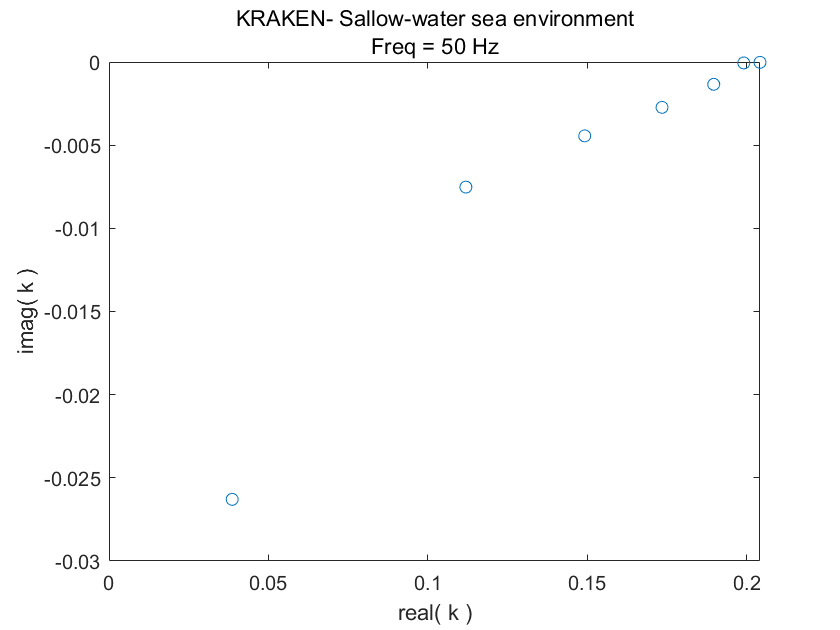

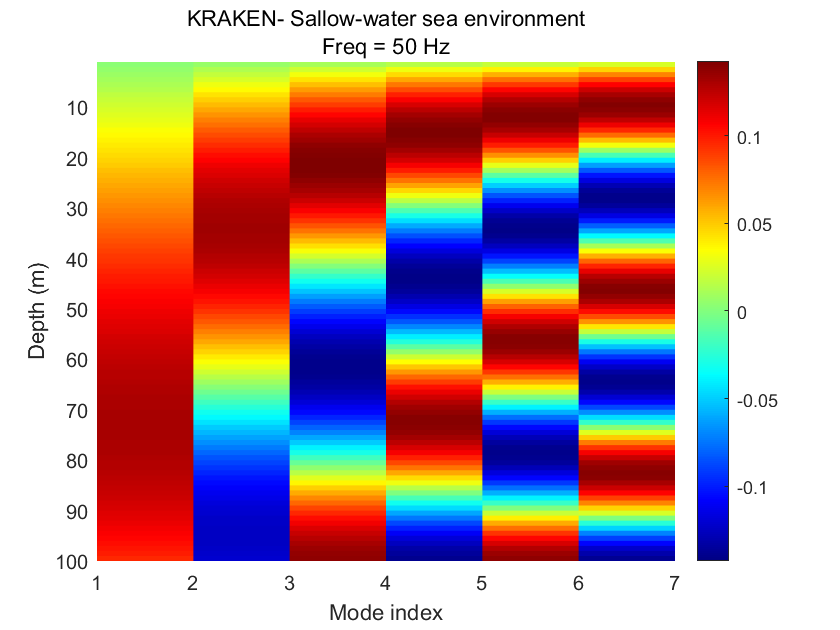

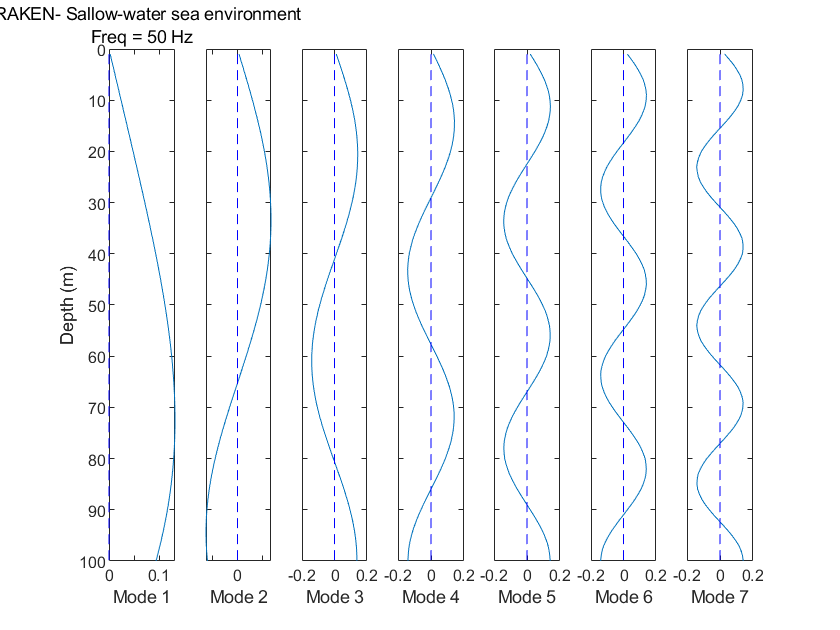

figure;
plotmode([flpfil '.mod'], 0)

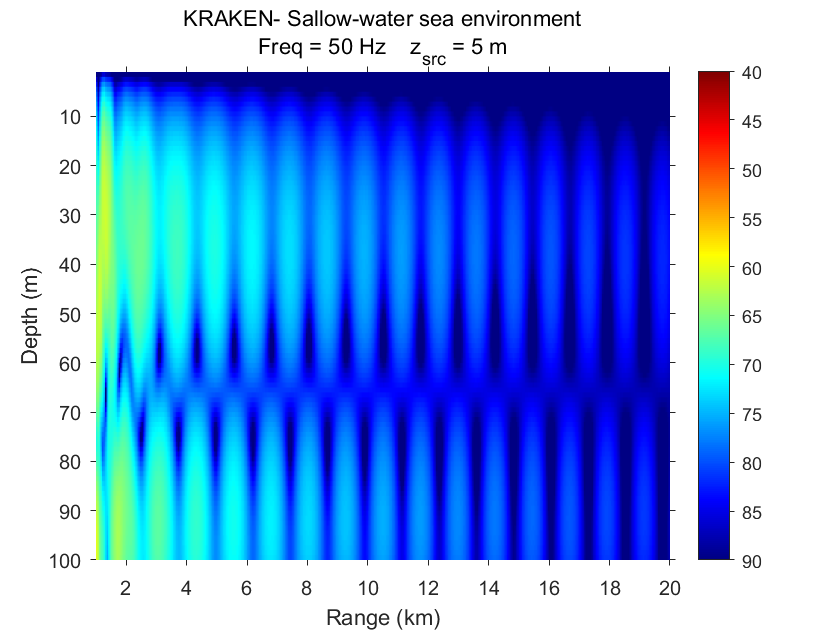

figure;
plotshd([flpfil '.shd.mat'])

## 2. Training dataset generation

### 2.1. Broadband env and flp file for training dataset

folder='..\1.1.2 Broadband Envfile';
if exist(folder, 'dir')==0 % Determine if a folder exists
    mkdir(folder);  % Create a folder when it does not exist
else
    disp('dir is exist'); % If the folder exists, output :dir is exist
end
cd(folder);          % Change the path to the environment file path

Bdry.Top.Opt = 'CVF  B'; % Top option
Pos.freqvec = 50: 200; % Broadband frequency vector
Pos.s.z = 1:100; % Sz(): Source   depths (m).
Pos.r.z = 22:3:73; % Rz(): Receiver depths (m).
envfil = 'SW_Training'; % env file name
% Write env
write_env( envfil, model, TitleEnv, freq, SSP, Bdry, Pos, Beam, cInt, RMax );
flpfil = envfil;
% Write flp
write_fieldflp( flpfil, Option, Pos );

### 2.2. Acoustic field calculation

krakenc(envfil)

### 2.3. Write to binary file

load([envfil '.shd.mat'], 'pressure') % Load data from .mat
folder = '..\1.1.3 Dataset\1.1.3.1 Training Set\(1) One environment training set';
if exist(folder, 'dir')==0 % Determine if a folder exists
    mkdir(folder);  % Create a folder when it does not exist
else
    disp('dir is exist'); % If the folder exists, output :dir is exist
end
filepath = [folder '\' envfil num2str(Pos.freqvec(1), '_%d') num2str(Pos.freqvec(end), '-%dHz_') ...
    num2str(Pos.r.r(1), '%.2f') num2str(Pos.r.r(end),'-%.2fkm.sim')]; % Training dataset file name
fid = fopen(filepath,'wb+'); % Create a binary file
% Write pressure to the binary file
for isd = 1: length(Pos.s.z) % Source depth circulation
    for isr = 1: length(Pos.r.r) % Source range circulation
        for ifreq = 1 :length(Pos.freqvec) % Source frequency circulation
            pr = reshape(squeeze(pressure(ifreq,isd,:,isr)).',[],1); % Take out the array received sound pressure from the data
            pr_nor = pr/ sqrt(pr' * pr); % N2 normalized
            fwrite(fid, real(pr_nor),'float32'); % Write real part pressure
            fwrite(fid, imag(pr_nor),'float32'); % Write image part pressure
        end
        fwrite(fid, Pos.r.r(isr),'float32'); % Write Source range
        fwrite(fid, Pos.s.z(isd),'float32'); % Write Source depth
    end
end

fclose(fid); % Close the binary file
fclose all;

% Check data size
D = dir(filepath);

if abs(D(end).bytes- (length(Pos.s.z) *length(Pos.r.r) *(length(Pos.freqvec)* 2*length(Pos.r.z)+2))* 4)< 1e-3
    fprintf('******************\n\n')
    fprintf('Pass the check!\n\n')
    fprintf('******************\n');
else
    fprintf('******************\n\n')
    fprintf('Failure to pass the data check! Please check the code.\n\n')
    fprintf('******************\n\n')
end
cd('..') % Change the path back

## 3. Validation dataset

### 3.1. Broadband env and flp file for training dataset

folder='..\1.1.2 Broadband Envfile';
if exist(folder, 'dir')==0 % Determine if a folder exists
    mkdir(folder);  % Create a folder when it does not exist
else
    disp('dir is exist'); % If the folder exists, output :dir is exist
end

dir is exist


cd(folder);          % Change the path to the environment file path

Bdry.Top.Opt = 'CVF  B'; % Top option
Pos.freqvec = 50: 200; % Broadband frequency vector
Pos.s.z = 1:100; % Sz(): Source   depths (m).
Pos.r.z = 22:3:73; % Rz(): Receiver depths (m).

SSP_V2 = SSP;
SSP_V2.depth(2) = 102; % Depth of the 2nd media (m).
SSP_V2.raw(1).z = [0: 5 : 100 SSP_V2.depth(2)]; % z():     Depth (m)
SSP_V2.Nz(1) = length(SSP_V2.raw(1).z); % Number of z vector
SSP_V2.raw(1).alphaR(1:SSP_V2.Nz(1)) = interp1(SSP.raw(1).z, SSP.raw(1).alphaR(1:SSP.Nz(1)), SSP_V2.raw(1).z, 'linear', 'extrap'); % alphaR():    P-wave speed (m/s).
SSP_V2.raw(1).betaR(1:SSP_V2.Nz(1)) = 0; % betaR():    S-wave speed (m/s).
SSP_V2.raw(1).rho(1:SSP_V2.Nz(1)) = 1.03; % rho():   Density (g/cm3).
SSP_V2.raw(1).alphaI(1:SSP_V2.Nz(1)) = 0; % alphaI():    P-wave attenuation (units as given in Block 2)
SSP_V2.raw(1).betaI(1:SSP_V2.Nz(1)) = 0; % betaI():    S-wave attenuation
SSP_V2.depth( SSP_V2.NMedia+1 ) = SSP_V2.depth(2); % depth:  Depth (m).

Bdry_V2 = Bdry;
Bdry_V2.Bot.HS.alphaR = 1632; % alphaR:  Bottom P-wave speed (m/s).
Bdry_V2.Bot.HS.betaR = 0; % betaR:  Bottom S-wave speed (m/s).
Bdry_V2.Bot.HS.rho = 1.8; % rho: Bottom density (g/cm3).
envfil = 'SW_Validation'; % env file name
% Write env
write_env( envfil, model, TitleEnv, freq, SSP_V2, Bdry_V2, Pos, Beam, cInt, RMax );
flpfil = envfil;
% Write flp
write_fieldflp( flpfil, Option, Pos );

### 3.2. Acoustic field calculation

krakenc(envfil)

___________________________________________________________________________
Running field.m


FileRoot = 'SW_Validation'


ext =

  空的 0×0 char 数组

/ ! Title 
RA  
MLimit = 999999 


_______________________ 

 Number of profiles, NProf = 1 

 Profile ranges, rProf (km) 
    0.00  

_______________________ 

 Number of receiver ranges, NRr = 381 

 Receiver ranges, Rr (km) 
    1.00 ...    20.00 

_______________________ 

 Number of source   depths, NSz   = 100 

 Source depths, Sz (m)
    1.00 ...   100.00 

_______________________ 

 Number of receiver depths, NRz   = 18 

 Receiver depths, Rz (m)
   22.00 ...    73.00 

_______________________ 

 Number of receiver range offsets (array tilt) = 18 

 Receiver range offsets, R.ro (m)
    0.00 ...     0.00 
  



### 3.3. Write to binary file

load([envfil '.shd.mat'], 'pressure') % Load data from .mat
folder = '..\1.1.3 Dataset\1.1.3.2 Validation Set\(1) One environment validation set';
if exist(folder, 'dir')==0 % Determine if a folder exists
    mkdir(folder);  % Create a folder when it does not exist
else
    disp('dir is exist'); % If the folder exists, output :dir is exist
end
filepath = [folder '\' envfil num2str(Pos.freqvec(1), '_%d') num2str(Pos.freqvec(end), '-%dHz_') ...
    num2str(Pos.r.r(1), '%.2f') num2str(Pos.r.r(end),'-%.2fkm.sim')]; % Training dataset file name
fid = fopen(filepath,'wb+'); % Create a binary file
% Write pressure to the binary file
for isd = 1: length(Pos.s.z) % Source depth circulation
    for isr = 1: length(Pos.r.r) % Source range circulation
        for ifreq = 1 :length(Pos.freqvec) % Source frequency circulation
            pr = reshape(squeeze(pressure(ifreq,isd,:,isr)).',[],1); % Take out the array received sound pressure from the data
            pr_nor = pr/ sqrt(pr' * pr); % N2 normalized
            fwrite(fid, real(pr_nor),'float32'); % Write real part pressure
            fwrite(fid, imag(pr_nor),'float32'); % Write image part pressure
        end
        fwrite(fid, Pos.r.r(isr),'float32'); % Write Source range
        fwrite(fid, Pos.s.z(isd),'float32'); % Write Source depth
    end
end

fclose(fid); % Close the binary file
fclose all;

% Check data size
D = dir(filepath);

if abs(D(end).bytes- (length(Pos.s.z) *length(Pos.r.r) *(length(Pos.freqvec)* 2*length(Pos.r.z)+2))* 4)< 1e-3
    fprintf('******************\n\n')
    fprintf('Pass the check!\n\n')
    fprintf('******************\n');
else
    fprintf('******************\n\n')
    fprintf('Failure to pass the data check! Please check the code.\n\n')
    fprintf('******************\n\n')
end

******************



Pass the check!



******************


cd('..') % Change the path back


## 3. Test dataset generation

### 3.1. Broadband env and flp file for validation dataset

folder='.\1.1.2 Broadband Envfile';
if exist(folder, 'dir')==0 % Determine if a folder exists
    mkdir(folder);  % Create a folder when it does not exist
else
    disp('dir is exist'); % If the folder exists, output :dir is exist
end
cd(folder);          % Change the path to the environment file path

Bdry.Top.Opt = 'CVF  B'; % Top option
Pos.freqvec = 50: 200; % Broadband frequency vector
Pos.s.z = 5:5:100; % Sz(): Source   depths (m).
Pos.r.z = 22:3:73; % Rz(): Receiver depths (m).
Pos.r.r = 1:0.25:20; % The receiver ranges (km)
envfil = 'SW_Test'; % env file name
ssp_shift_vec = -20:1:20; % Sound speed shift (m/s)
for i_depth_shift = 1 : length(ssp_shift_vec)
    SSP.raw(1).alphaR(1:SSP.Nz(1)) = (1540:-1:1520) + ssp_shift_vec(i_depth_shift); % alphaR():    P-wave speed (m/s).
    % Write env
    write_env( envfil, model, TitleEnv, freq, SSP, Bdry, Pos, Beam, cInt, RMax );
    flpfil = envfil;
    % Write flp
    write_fieldflp( flpfil, Option, Pos );

### 3.2. Acoustic field calculation

    krakenc(envfil)

### 3.3. Write to binary file

    load([envfil '.shd.mat'], 'pressure'); % Load data from .mat
    folder = '..\1.1.3 Dataset\1.1.3.2 Test Set\(1) Sound speed profile shift';
    if exist(folder, 'dir')==0 % Determine if a folder exists
        mkdir(folder);  % Create a folder when it does not exist
    else
        disp('dir is exist'); % If the folder exists, output :dir is exist
    end

    filepath = [folder '\' num2str(i_depth_shift,'%02d_') envfil num2str(Pos.freqvec(1), '_%d') num2str(Pos.freqvec(end), '-%dHz_') ...
        num2str(Pos.r.r(1), '%.2f') num2str(Pos.r.r(end),'-%.2fkm') num2str(ssp_shift_vec(i_depth_shift),'ssp%.1fm.sim')]; % Training dataset file name
    fid = fopen(filepath,'wb+'); % Create a binary file
    % Write pressure to the binary file
    for isd = 1: length(Pos.s.z) % Source depth circulation
        for isr = 1: length(Pos.r.r) % Source range circulation
            for ifreq = 1 :length(Pos.freqvec) % Source frequency circulation
                pr = reshape(squeeze(pressure(ifreq,isd,:,isr)).',[],1); % Take out the array received sound pressure from the data
                pr_nor = pr/ sqrt(pr' * pr); % N2 normalized
                fwrite(fid, real(pr_nor),'float32'); % Write real part pressure
                fwrite(fid, imag(pr_nor),'float32'); % Write image part pressure
            end
            fwrite(fid, Pos.r.r(isr),'float32'); % Write Source range
            fwrite(fid, Pos.s.z(isd),'float32'); % Write Source depth
        end
    end
    fclose(fid); % Close the binary file
    fclose all; % All open files must be closed, too many open files in the loop will cause matlab to jam
end
% Check data size
D = dir(filepath);
if abs(D(end).bytes- (length(Pos.s.z) *length(Pos.r.r) *(length(Pos.freqvec)* 2*length(Pos.r.z)+2))* 4)< 1e-3
    fprintf('******************\n\n')
    fprintf('Pass the check!\n\n')
    fprintf('******************\n');
else
    fprintf('******************\n\n')
    fprintf('Failure to pass the data check! Please check the code.\n\n')
    fprintf('******************\n');
end
cd('..') % Change the path back
%%

## 4. Measured data (pseudo)

### 4.1. Broadband env and flp file for validation dataset

folder='.\1.1.2 Broadband Envfile';
if exist(folder, 'dir')==0 % Determine if a folder exists
    mkdir(folder);  % Create a folder when it does not exist
else
    disp('dir is exist'); % If the folder exists, output :dir is exist
end
cd(folder);          % Change the path to the environment file path
Bdry.Top.Opt = 'CVF  B'; % Top option
Pos.freqvec = 50: 200; % Broadband frequency vector
Pos.s.z = [5 55]; % Sz(): Source   depths (m).
Pos.r.z = 22:3:73; % Rz(): Receiver depths (m).
Pos.r.r = 1:1:20; % The receiver ranges (km)
envfil = 'SW_Exp'; % env file name
ssp_shift_vec = 0; % Sound speed shift (m/s)
% Write env
write_env( envfil, model, TitleEnv, freq, SSP, Bdry, Pos, Beam, cInt, RMax );
flpfil = envfil;
% Write flp
write_fieldflp( flpfil, Option, Pos );

### 4.2. Acoustic field calculation

krakenc(envfil)

### 4.3. Write to binary file

load([envfil '.shd.mat'], 'pressure') % Load data from .mat
folder = '..\1.1.3 Dataset\1.1.3.3 Measured Set\(1) One environment measured set';
if exist(folder, 'dir')==0 % Determine if a folder exists
    mkdir(folder);  % Create a folder when it does not exist
else
    disp('dir is exist'); % If the folder exists, output :dir is exist
end
filepath = [folder '\' envfil num2str(Pos.freqvec(1), '_%d') num2str(Pos.freqvec(end), '-%dHz_') ...
    num2str(Pos.r.r(1), '%.2f') num2str(Pos.r.r(end),'-%.2fkm.sim')]; % Training dataset file name
fid = fopen(filepath,'wb+'); % Create a binary file
% Write pressure to the binary file
for isd = 1: length(Pos.s.z) % Source depth circulation
    for isr = 1: length(Pos.r.r) % Source range circulation
        for ifreq = 1 :length(Pos.freqvec) % Source frequency circulation
            pr = reshape(squeeze(pressure(ifreq,isd,:,isr)).',[],1); % Take out the array received sound pressure from the data
            pr_nor = pr/ sqrt(pr' * pr); % N2 normalized
            fwrite(fid, real(pr_nor),'float32'); % Write real part pressure
            fwrite(fid, imag(pr_nor),'float32'); % Write image part pressure
        end
        fwrite(fid, Pos.r.r(isr),'float32'); % Write Source range
        fwrite(fid, Pos.s.z(isd),'float32'); % Write Source depth
    end
end

fclose(fid); % Close the binary file
fclose all;

% Check data size
D = dir(filepath);

if abs(D(end).bytes- (length(Pos.s.z) *length(Pos.r.r) *(length(Pos.freqvec)* 2*length(Pos.r.z)+2))* 4)< 1e-3
    fprintf('******************\n\n')
    fprintf('Pass the check!\n\n')
    fprintf('******************\n');
else
    fprintf('******************\n\n')
    fprintf('Failure to pass the data check! Please check the code.\n\n')
    fprintf('******************\n\n')
end
cd('..') % Change the path back